n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 4;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

p_vec =  linspace(1,50,50)*100;
n_rep = 100;
n_pararell = 12;
n_p_chunk = floor(50/n_pararell);
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    if i == n_pararell
         p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : end )
    end
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end

p_vec_chunk = 1×12 cell array
    {[100 200 300 400]}    {[500 600 700 800]}    {[900 1000 1100 1200]}    {[1300 1400 1500 1600]}    {[1700 1800 1900 2000]}    {[2100 2200 2300 2400]}    {[2500 2600 2700 2800]}    {[2900 3000 3100 3200]}    {[3300 3400 3500 3600]}    {[3700 3800 3900 4000]}    {[4100 4200 4300 4400]}    {[4500 4600 4700 4800 4900 5000]}


tic
% parallel for loop
parfor w = 1 : n_pararell
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans_hc_init_ver_01_11_24_parallel(x, sigma, K,  n_iter, rounding, cluster_true);
    end
end
end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1

toc

Elapsed time is 31530.930242 seconds.


clustering_acc_mat_chunk{13} = repmat( repelem(0, 2 ), n_rep, 1 );

tic
    p = 4900

p = 4900

    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
        % iterate
 
        clustering_acc_mat_chunk{13}(1, i) = iterative_kmeans_hc_init_ver_01_11_24_parallel(x, sigma, K,  n_iter, rounding, cluster_true);
    end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual


toc


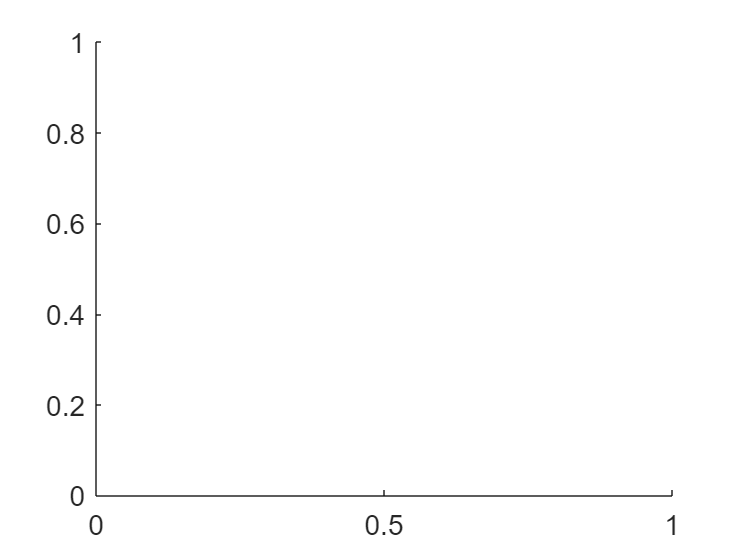


plot(x,y)

plot(x,y_max,'red')

Error using plot
Vectors must be the same length.

plot(x,y_min,'red')
hold off